%Начало обработки по 3 параметрам

rho_brain_min = 1/0.717;
rho_brain_max = 1/0.066;	
rho_skin_min = 1/0.726;	
rho_skin_max = 1/0.024;	
rho_scull_min = 1/0.2; 
rho_scull_max = 1/0.002; 

rho_skin = rho_skin_min:(rho_skin_max - rho_skin_min)/9:rho_skin_max;
rho_scull = rho_scull_min:(rho_scull_max - rho_scull_min)/9:rho_scull_max;
rho_brain = rho_brain_min:(rho_brain_max - rho_brain_min)/9:rho_brain_max;

rho_skin_min = 1;
rho_skin_max = 5;
rho_skin = 1:1:5;
rho_scull = 40:10:70;
rho_brain = 1:1:5;

%Деление на подмассивы
data_br_big = {};
data_fh_big = {};
data_fh_small = {};
data_fh_micro = {};
j = 1;
for i=1:length(rho_brain):length(imp_fh_small)
    data_br_big{j} = imp_brain_big(i:(i+length(rho_brain)-1));
    data_fh_big{j} = imp_fh_big(i:(i+length(rho_brain)-1));
    data_fh_small{j} = imp_fh_small(i:(i+length(rho_brain)-1));
    data_fh_micro{j} = imp_fh_micro(i:(i+length(rho_brain)-1));
    j = j+1;
end

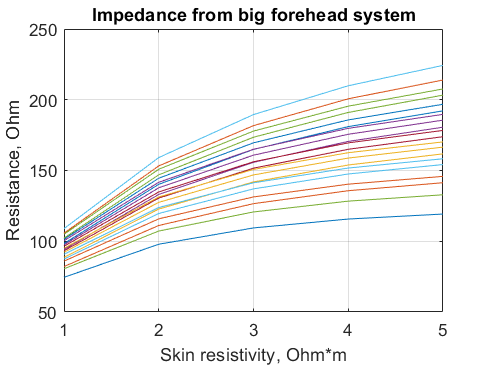

%Построение графиков от ро кожи
for i=1:1:(length(data_fh_micro)/1)
    plot(rho_skin,data_fh_big{i})
    hold on
end
grid on
title("Impedance from big forehead system")
xlabel("Skin resistivity, Ohm*m")
ylabel("Resistance, Ohm")
hold off

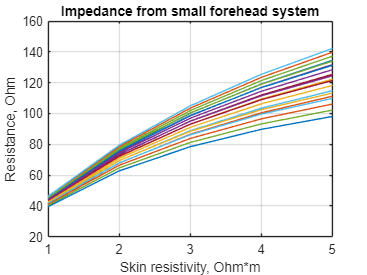

for i=1:1:(length(data_fh_micro)/1)
    plot(rho_skin,data_fh_small{i})
    hold on
end
grid on
title("Impedance from small forehead system")
xlabel("Skin resistivity, Ohm*m")
ylabel("Resistance, Ohm")
hold off

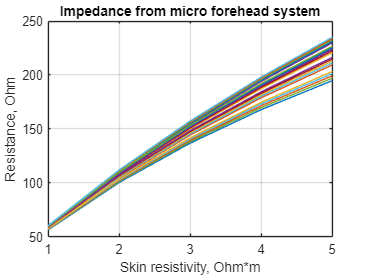

for i=1:1:(length(data_fh_micro)/1)
    plot(rho_skin,data_fh_micro{i})
    hold on
end
grid on
title("Impedance from micro forehead system")
xlabel("Skin resistivity, Ohm*m")
ylabel("Resistance, Ohm")
hold off

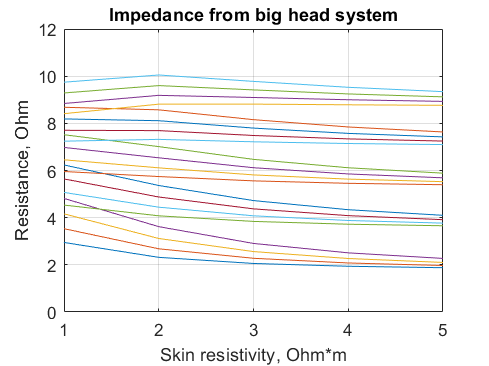

for i=1:1:(length(data_fh_micro)/1)
    plot(rho_skin,data_br_big{i})
    hold on
end
grid on
title("Impedance from big head system")
xlabel("Skin resistivity, Ohm*m")
ylabel("Resistance, Ohm")
hold off

%Подбор аппроксимации через curve fitting
d_fh_big = data_fh_big{length(data_fh_micro)/2};
d_br_big = data_br_big{length(data_fh_micro)/2};
d_fh_small = data_fh_small{length(data_fh_micro)/2};
d_fh_micro = data_fh_micro{length(data_fh_micro)/2};

%Работаем с суммой двух экспонент
c_br_big = {};
c_fh_big = {};
c_fh_small = {};
c_fh_micro = {};
for i = 1:1:length(data_br_big)
    c_br_big{i} = coeffvalues(fit(transpose(rho_skin),data_br_big{i},'exp2'));
    c_fh_big{i} = coeffvalues(fit(transpose(rho_skin),data_fh_big{i},'exp2'));
    c_fh_small{i} = coeffvalues(fit(transpose(rho_skin),data_fh_small{i},'exp2'));
    c_fh_micro{i} = coeffvalues(fit(transpose(rho_skin),data_fh_micro{i},'exp2'));
end

%Увеличение количества точек для анализа
rho_skin1 = rho_skin_min:(rho_skin_max-rho_skin_min)/10000:rho_skin_max;
db_br_big = {};
db_fh_big = {};
db_fh_small = {};
db_fh_micro = {};
for i = 1:1:length(data_br_big)
    db_br_big{i} = exp2(rho_skin1,c_br_big{i});
    db_fh_big{i} = exp2(rho_skin1,c_fh_big{i});
    db_fh_small{i} = exp2(rho_skin1,c_fh_small{i});
    db_fh_micro{i} = exp2(rho_skin1,c_fh_micro{i});
end

% Опорные значения базового импеданса
base_br_big = 60.7; % В Ом
base_fh_big = 125.6;
base_fh_small = 72.6;
base_fh_micro = 130; % Взято с меня

% Подбор интересующих точек
eps = 1;
count_br_big = 1;
count_fh_big = 1;
count_fh_small = 1;
count_fh_micro = 1;

points_br_big = {};
points_scull_br_big = [];
p_br_big = [];
points_brain_br_big = [];
p_fin_skin_br_big = {};
p_fin_scull_br_big = {};
p_fin_brain_br_big = {};


points_fh_big = {};
points_scull_fh_big = [];
p_fh_big = [];
points_brain_fh_big = [];
p_fin_skin_fh_big = [];
p_fin_scull_fh_big = [];
p_fin_brain_fh_big = [];


points_fh_small = {};
points_scull_fh_small = [];
p_fh_small = [];
points_brain_fh_small = [];
p_fin_skin_fh_small = [];
p_fin_scull_fh_small = [];
p_fin_brain_fh_small = [];

points_fh_micro = {};
points_scull_fh_micro = [];
p_fh_micro = [];
points_brain_fh_micro = [];
p_fin_skin_fh_micro = [];
p_fin_scull_fh_micro = [];
p_fin_brain_fh_micro = [];


for i = 1:1:length(data_br_big)
    points_scull_br_big = [];
    points_brain_br_big = [];
    p_br_big = [];
    points_br_big{i} = find(abs(db_br_big{i} - base_br_big)<eps);
    if (~isnan(points_br_big{i}))
        for j = 1:1:length(points_br_big{i})
            if (mod(i,length(rho_scull)) == 0)
                k = length(rho_scull);
            else
                k = mod(i,length(rho_scull));
            end
            if (mod(floor(i/length(rho_scull))+1,length(rho_brain)) == 0)
                l = 10;
            elseif (mod(i,length(rho_scull)) == 0)
                l = i/length(rho_scull);
            else
                l = mod(floor(i/length(rho_scull))+1,length(rho_brain));
            end
            points_scull_br_big = [points_scull_br_big rho_scull(k)];
            points_brain_br_big = [points_brain_br_big rho_brain(l)];
            p_br_big = [p_br_big rho_skin1(points_br_big{i}(j))];
        end
        p_fin_skin_br_big{count_br_big} = p_br_big ;
        p_fin_scull_br_big{count_br_big} = points_scull_br_big;
        p_fin_brain_br_big{count_br_big} = points_brain_br_big;
        count_br_big = count_br_big + 1;
    end
    points_scull_fh_big = [];
    points_brain_fh_big = [];
    p_fh_big = [];
    points_fh_big{i} = find(abs(db_fh_big{i} - base_fh_big)<eps);
    if (~isnan(points_fh_big{i}))
        for j = 1:1:length(points_fh_big{i})
                        if (mod(i,length(rho_scull)) == 0)
                k = length(rho_scull);
            else
                k = mod(i,length(rho_scull));
            end
            if (mod(floor(i/length(rho_scull))+1,length(rho_brain)) == 0)
                l = length(rho_brain);
            elseif (mod(i,length(rho_scull)) == 0)
                l = i/length(rho_scull);
            else
                l = mod(floor(i/length(rho_scull))+1,length(rho_brain));
            end
            points_scull_fh_big = [points_scull_fh_big rho_scull(k)];
            points_brain_fh_big = [points_brain_fh_big rho_brain(l)];
            p_fh_big = [p_fh_big rho_skin1(points_fh_big{i}(j))];
        end
        p_fin_skin_fh_big = [p_fin_skin_fh_big p_fh_big(1)]  ;
        p_fin_scull_fh_big = [p_fin_scull_fh_big points_scull_fh_big(1)];
        p_fin_brain_fh_big = [p_fin_brain_fh_big points_brain_fh_big(1)];
        count_fh_big = count_fh_big + 1;
    end
    points_scull_fh_small = [];
    points_brain_fh_small = [];
    p_fh_small = [];
    points_fh_small{i} = find(abs(db_fh_small{i} - base_fh_small)<eps);
    if (~isnan(points_fh_small{i}))
        for j = 1:1:length(points_fh_small{i})
                        if (mod(i,length(rho_scull)) == 0)
                k = length(rho_scull);
            else
                k = mod(i,length(rho_scull));
            end
            if (mod(floor(i/length(rho_scull))+1,length(rho_brain)) == 0)
                l = length(rho_brain);
            elseif (mod(i,length(rho_scull)) == 0)
                l = i/length(rho_scull);
            else
                l = mod(floor(i/length(rho_scull))+1,length(rho_brain));
            end
            points_scull_fh_small = [points_scull_fh_small rho_scull(k)];
            points_brain_fh_small = [points_brain_fh_small rho_brain(l)];
            p_fh_small = [p_fh_small rho_skin1(points_fh_small{i}(j))];
        end
        p_fin_skin_fh_small = [p_fin_skin_fh_small p_fh_small(1)]  ;
        p_fin_scull_fh_small = [p_fin_scull_fh_small points_scull_fh_small(1)];
        p_fin_brain_fh_small = [p_fin_brain_fh_small points_brain_fh_small(1)];
        count_fh_small = count_fh_small + 1;
    end
    points_scull_fh_micro = [];
    points_brain_fh_micro = [];
    p_fh_micro = [];
    points_fh_micro{i} = find(abs(db_fh_micro{i} - base_fh_micro)<eps);
        if (~isnan(points_fh_micro{i}))
        for j = 1:1:length(points_fh_micro{i})
            if (mod(i,length(rho_scull)) == 0)
                k = length(rho_scull);
            else
                k = mod(i,length(rho_scull));
            end
            if (mod(floor(i/length(rho_scull))+1,length(rho_brain)) == 0)
                l = length(rho_brain);
            elseif (mod(i,length(rho_scull)) == 0)
                l = i/length(rho_scull);
            else
                l = mod(floor(i/length(rho_scull))+1,length(rho_brain));
            end
            points_scull_fh_micro = [points_scull_fh_micro rho_scull(k)];
            points_brain_fh_micro = [points_brain_fh_micro rho_brain(l)];
            p_fh_micro = [p_fh_micro rho_skin1(points_fh_micro{i}(j))];
        end
        p_fin_skin_fh_micro = [p_fin_skin_fh_micro p_fh_micro(1)]  ;
        p_fin_scull_fh_micro = [p_fin_scull_fh_micro points_scull_fh_micro(1)];
        p_fin_brain_fh_micro = [p_fin_brain_fh_micro points_brain_fh_micro(1)];
        count_fh_micro = count_fh_micro + 1;
    end
end

% Найти индексы уникальных значений в массиве уд сопр мозга
[UN1,i_un_brain_fh_micro] = unique(p_fin_brain_fh_micro);
[UN2,i_un_brain_fh_small] = unique(p_fin_brain_fh_small);
[UN3,i_un_brain_fh_big] = unique(p_fin_brain_fh_big);
for i = 1: 1: (length(i_un_brain_fh_micro)-1)
    skin_data_fh_micro{i} = p_fin_skin_fh_micro(i_un_brain_fh_micro(i):(i_un_brain_fh_micro(i+1)-1));
    scull_data_fh_micro{i} = p_fin_scull_fh_micro(i_un_brain_fh_micro(i):(i_un_brain_fh_micro(i+1)-1));
end
for i = 1: 1: (length(i_un_brain_fh_small)-1)
    skin_data_fh_small{i} = p_fin_skin_fh_small(i_un_brain_fh_small(i):(i_un_brain_fh_small(i+1)-1));
    scull_data_fh_small{i} = p_fin_scull_fh_small(i_un_brain_fh_small(i):(i_un_brain_fh_small(i+1)-1));
end
for i = 1: 1: (length(i_un_brain_fh_big)-1)
    skin_data_fh_big{i} = p_fin_skin_fh_big(i_un_brain_fh_big(i):(i_un_brain_fh_big(i+1)-1));
    scull_data_fh_big{i} = p_fin_scull_fh_big(i_un_brain_fh_big(i):(i_un_brain_fh_big(i+1)-1));
end

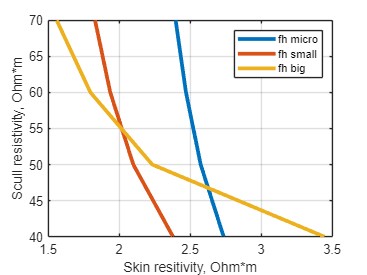

% НАКОНЕЦ-ТО
plot(skin_data_fh_micro{2},scull_data_fh_micro{2},LineWidth=3)
hold on
plot(skin_data_fh_small{2},scull_data_fh_small{2},LineWidth=3)
plot(skin_data_fh_big{2},scull_data_fh_big{2},LineWidth=3)
hold off
grid on
xlabel("Skin resitivity, Ohm*m")
ylabel("Scull resistivity, Ohm*m")
legend(["fh micro" "fh small" "fh big"])

% Снова для curve fitting
d_skin = skin_data_fh_micro{2};
d_scull = scull_data_fh_micro{2};

% Снова через сумму двух экспонент. Тестово для двух графиков
skin2 = 2:(10-2)/10000:10;
for i = 1:1:min([length(skin_data_fh_micro), length(skin_data_fh_small), length(skin_data_fh_big)])
if (length(skin_data_fh_micro{i}) >=4)
    coeff_fh_micro{i} = coeffvalues(fit(transpose(skin_data_fh_micro{i}),transpose(scull_data_fh_micro{i}),'exp2'));
    data_fit_fh_micro{i} = exp2(skin2,coeff_fh_micro{i});
end
if (length(skin_data_fh_small{i}) >=4)
    coeff_fh_small{i} = coeffvalues(fit(transpose(skin_data_fh_small{i}),transpose(scull_data_fh_small{i}),'exp2'));
data_fit_fh_small{i} = exp2(skin2,coeff_fh_small{i});
end
    if (length(skin_data_fh_big{i}) >=4)
coeff_fh_big{i} = coeffvalues(fit(transpose(skin_data_fh_big{i}),transpose(scull_data_fh_big{i}),'exp2'));
data_fit_fh_big{i} = exp2(skin2,coeff_fh_big{i});
end



end

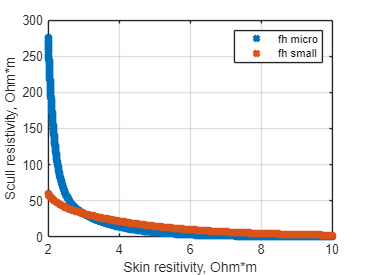

hold off

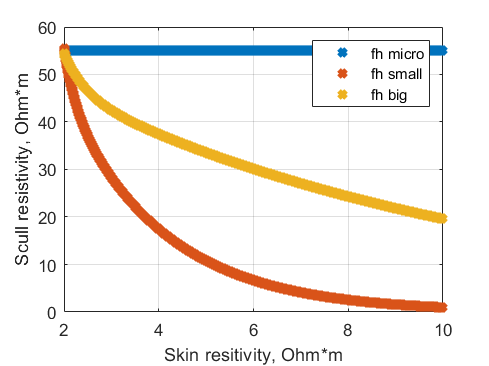

plot(skin2,data_fit_fh_micro{2},'x',LineWidth=3)
hold on
plot(skin2,data_fit_fh_small{2} ,'x',LineWidth=3)
plot(skin2,data_fit_fh_big{2} ,'x',LineWidth=3)
%plot(skin_data_fh_big{1},scull_data_fh_big{1},'x',LineWidth=3)
hold off
grid on
xlabel("Skin resitivity, Ohm*m")
ylabel("Scull resistivity, Ohm*m")
legend(["fh micro" "fh small" "fh big"])

% Ищу пересечения между интерполированными графиками
eps1 = 3;
skin_scull_intersect_ind = [];
skin_intersect_small_big = [];
scull_intersect_small_big = [];
skin_fh_big = [];
scull_fh_big = [];
for i = 2:1:min([length(skin_data_fh_micro), length(skin_data_fh_small), length(data_fit_fh_micro)])
    skin_scull_intersect = find((abs(data_fit_fh_small{i}-data_fit_fh_micro{i}) < eps1) & (abs(data_fit_fh_small{i}-data_fit_fh_big{i}) < eps1));
    if (~isnan(skin_scull_intersect))
    skin_scull_intersect_ind = [ skin_scull_intersect_ind skin_scull_intersect(1)];
    skin_intersect_small_big = [skin_intersect_small_big skin2(skin_scull_intersect(1))];
    scull_intersect_small_big = [scull_intersect_small_big data_fit_fh_small{i}(skin_scull_intersect(1))];
    skin_fh_big = [skin_fh_big, skin_data_fh_big{i}];
    scull_fh_big = [scull_fh_big, scull_data_fh_big{i}];
    i
    end
end

i = 2

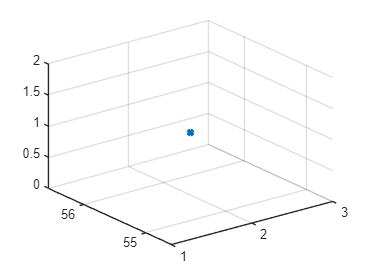

plot3(skin_intersect_small_big,scull_intersect_small_big,rho_brain(1:length(scull_intersect_small_big)),'x',LineWidth=3);
hold on
%plot3(skin_fh_big,scull_fh_big,rho_brain(1:7),LineWidth=3);
hold off
grid on

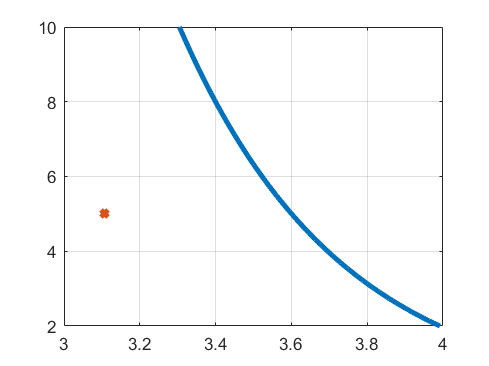

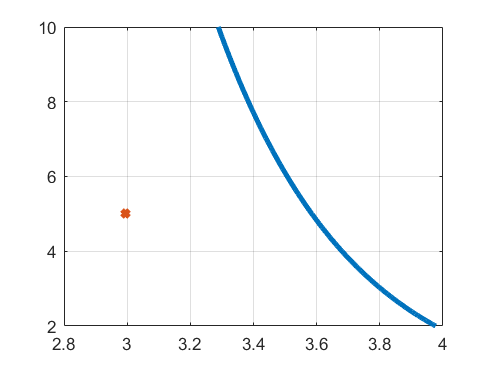

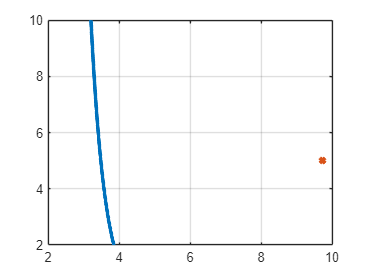

distances = [];
mins = [];
for i = 1:1:3
    figure(i)
    distances = [];
    plot(skin2,data_fit_fh_micro{i},skin_intersect_small_big(i),scull_intersect_small_big(i),'x',LineWidth=3);
    ylim([2,10]);
    grid on
    for j = 1:1:length(skin2)
    distances = [distances sqrt((skin2(j) - skin_intersect_small_big(i)).^2 + (data_fit_fh_micro{i}(j)-scull_intersect_small_big(i)).^2)] ;
    end
    mins = [mins min(distances)];
end

distances

distances =   593.7947  587.6092  581.5093  575.4938  569.5614  563.7110  557.9412  552.2511  546.6393  541.1048  535.6464  530.2631  524.9537  519.7171  514.5524  509.4584  504.4342  499.4786  494.5908  489.7697  485.0144  480.3239  475.6973  471.1335  466.6319  462.1913  457.8110  453.4900  449.2276  445.0228  440.8748  436.7828  432.7460  428.7636  424.8347  420.9587  417.1347  413.3620  409.6399  405.9676  402.3444  398.7695  395.2424  391.7622  388.3284  384.9402  381.5970  378.2981  375.0429  371.8308


[val,ind] = min(sqrt((data_fit_fh_micro{2}-scull_intersect_small_big(2)).^2+(skin2 - skin_intersect_small_big(2)).^2))

val = 0.4886

ind = 1882

data_fit_fh_micro{2}(ind)

ans = 6.0298

skin2(ind)

ans = 3.5048

[val,id] = min(mins)

val = 0.4903

id = 1

rho_brain(id)

ans = 1.3947

skin_intersect_small_big(id)

ans = 3.1080

scull_intersect_small_big(id)

ans = 5.0052

plot(skin_data_fh_big{1},scull_data_fh_big{1},'x',LineWidth=3)

plot3(p_fh_small,points_scull_fh_small, points_brain_fh_small, LineWidth=3)
hold on
plot3(p_fh_big,points_scull_fh_big, points_brain_fh_big, LineWidth=3)
plot3(p_fh_micro,points_scull_fh_micro, points_brain_fh_micro, LineWidth=3)
plot3(p_br_big,points_scull_br_big, points_brain_br_big, LineWidth=3)
hold off
legend(["fh small" "fh big" "fh micro" "br big"])
xlabel("Skin resistivity, Ohm*m")
ylabel("Scull resistivity, Ohm*m")
zlabel("Brain resistivity, Ohm*m")

plot(p_fh_small,points_scull_fh_small, LineWidth=3)
hold on
plot(p_fh_big,points_scull_fh_big, LineWidth=3)
plot(p_fh_micro,points_scull_fh_micro, LineWidth=3)
hold off
grid on
legend(["fh small" "fh big" "fh micro"])
xlabel("Skin resistivity, Ohm*m")
ylabel("Scull resistivity, Ohm*m")


i1 = 1;
i2 = 1;
i3 = 1;
i4 = 1;
for i = 1:1:length(data_br_big)
    
end


%Тестовое построение 3-хмерного массива
plot3(rho_scull0,rho_skin0,imp_brain_big,LineStyle=":")

%Конец обработки по 3 параметрам

data = data_big_close{1}

data1 = data_to_analysis_far{1}

data_to_analysis_far = {}
data_to_analysis_close = {}
for i = 1:31:(217-31+1)
    data_to_analysis_far{(round(i/31)+1)} = imp_far(i:(i+30))
    data_to_analysis_close{(round(i/31)+1)} = imp_close(i:(i+30))
end
fit_coeffs_far = {};
fit_coeffs_close = {};
for i = 1:1:7
    fit_coeffs_far{i} = coeffvalues(fit(transpose(rho_scull),data_to_analysis_far{i},'exp2'));
    fit_coeffs_close{i} = coeffvalues(fit(transpose(rho_scull),data_to_analysis_close{i},'exp2'));
end

x = 50:0.0005:90;
data_big_far = {}
data_big_close = {}
for i = 1:1:7
    data_big_far{i} = fit_coeffs_far{i}(1)*exp(fit_coeffs_far{i}(2)*x)+fit_coeffs_far{i}(3)*exp(fit_coeffs_far{i}(4)*x);
    data_big_close{i} = fit_coeffs_close{i}(1)*exp(fit_coeffs_close{i}(2)*x)+fit_coeffs_close{i}(3)*exp(fit_coeffs_close{i}(4)*x);
end

eps = 0.1;
rho_skin_fin_far = zeros(1,7);
rho_skin_fin_close = zeros(1,7);
for i = 1:1:7
    ind_far = find(abs(data_big_far{i} - 125.6)<eps);
    if (~isnan(ind_far))
    rho_skin_fin_far(i) = x(ind_far(1));
    end

    ind_close = find(abs(data_big_close{i} - 72.6)<eps);
    if (~isnan(ind_close))
    rho_skin_fin_close(i) = x(ind_close(1));
    end
     
end
plot(rho_skin_fin_far,rho_skin,rho_skin_fin_close,rho_skin)
grid on

xx = 2:0.0005:5
coef_far = coeffvalues(fit(transpose(rho_skin_fin_far),transpose(rho_scull),'exp2'))
coef_close = coeffvalues(fit(transpose(rho_skin_fin_close),transpose(rho_scull),'exp1'))
f_far = coef_far(1)*exp(coef_far(2)*xx)+coef_far(3)*exp(coef_far(4)*xx);
f_close = coef_close(1)*exp(coef_close(2)*xx);

plot(xx,f_far,xx,f_close)


eps1 = 0.1;
intersection = find(abs(f_far-f_close) < eps1)
f_close(intersection)
xx(intersection)

%far 
%       a =        2299  (-1822, 6421)
 %      b =      -1.248  (-1.996, -0.501)
  %     c =   1.774e-05  (-0.000952, 0.0009874)
   %    d =        4.38  (-13.15, 21.91)


%close
%       a =           0
 %      b =      -43.68
  %     c =   4.075e+04  (2.54e+04, 5.61e+04)
   %    d =      -1.864  (-1.976, -1.753)

f_far = 2299*exp(-1.248*xx)+1.774e-05*exp(4.38*xx);
f_close = 0*exp(-43.68*xx)+4.075e+04*exp(-1.864*xx);
plot(xx,f_far,xx,f_close)

x1 = [2.68, 2.938, 3.4271, 4.9141, 35]
y1 = [200, 150, 100, 50, 10]
x2 = [3.3326, 3.4724, 3.7397, 4.5037, 9.8181]

%Секция функций. НЕ ТРОГАТЬ
% Работаем, как всегда, с суммой двух экспонент

function res = exp2(arr,coeffs)
    res = coeffs(1)*exp(coeffs(2)*arr)+ coeffs(3)*exp(coeffs(4)*arr);
end